# Analysis of Wind Turbine data -- EOC

#### Dataset: D1C4SG1 -- EOC labeled data 

#### Author: Vishu Sharma

#### Last Modified: 21.02.2023

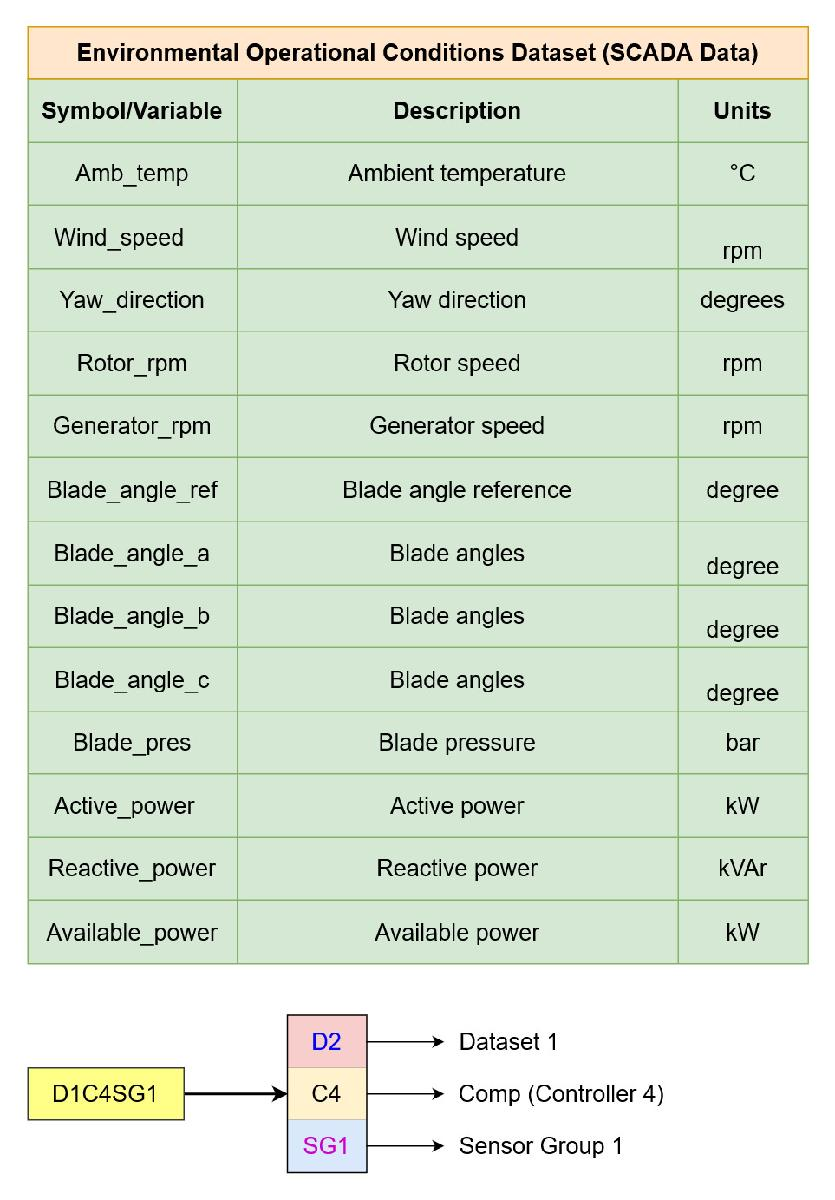

clear all, clc

% Loading data sets from CSV files

A = readmatrix("D:\University of Siegen\uos\research Project\Codes\Data\WT_labeled_data\D1C4SG1_EOC_Labeled.csv");

% Labeled variables

Amb_temp     = A(:,1);
Wind_speed	 = A(:,2);
Rotor_rpm    = A(:,4);
Generator_rpm  = A(:,5);

% Constructing time vector 

Fs = 1;            % Sampling frequency
T = 1/Fs;          % Sampling period
L = 600;           % length of signal
t = (0: L-1)*T;    % Time vector

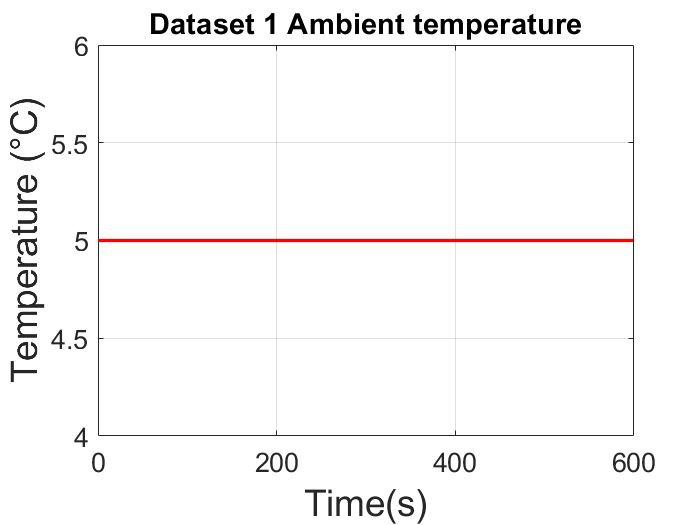

% Time Domain preliminary analysis -- Ambient Temperature

plot(t, Amb_temp, 'r','LineWidth',2)
title('Dataset 1 Ambient temperature','FontSize', 22)

ax = gca;
ax.FontSize = 16;
xlabel('Time(s)','FontSize', 22)
ylabel('Temperature (°C)', 'FontSize', 22)

grid on

mean(Amb_temp)

ans = 5

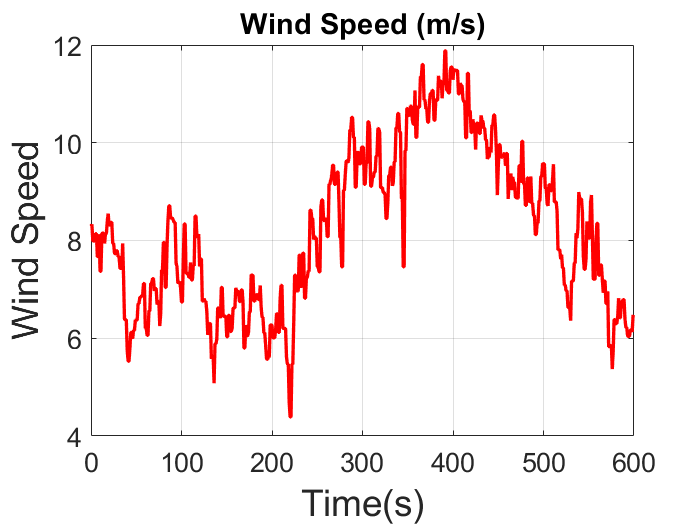

% Time Domain preliminary analysis -- Wind Speed

plot(t, Wind_speed, 'r','LineWidth',2)
title('Wind Speed (m/s)','FontSize', 22)

ax = gca;
ax.FontSize = 16;
xlabel('Time(s)','FontSize', 22)
ylabel('Wind Speed', 'FontSize', 22)

grid on

mean(Wind_speed)

ans = 8.2446

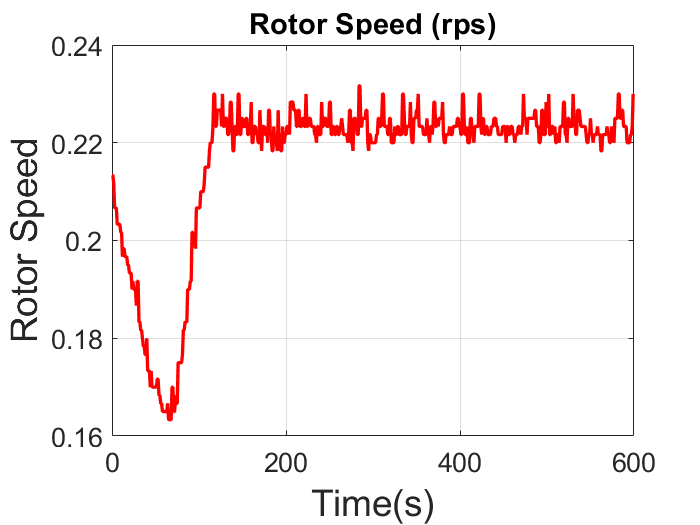

% Time Domain preliminary analysis -- Rotor speed

Rotor_rps = 1/60 * Rotor_rpm;  % converting from rpm to rps

plot(t, Rotor_rps, 'r','LineWidth',2)
title('Rotor Speed (rps)','FontSize', 22)

ax = gca;
ax.FontSize = 16;
xlabel('Time(s)','FontSize', 22)
ylabel('Rotor Speed', 'FontSize', 22)

grid on

mean(Rotor_rps)

ans = 0.2165

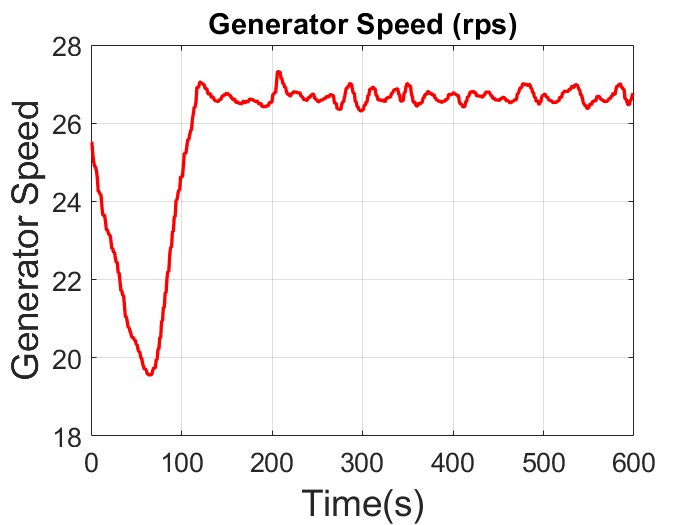

% Time Domain preliminary analysis -- Rotor speed

Generator_rps = 1/60 * Generator_rpm;  % Converting from rpm to rps

plot(t, Generator_rps, 'r','LineWidth',2)
title('Generator Speed (rps)','FontSize', 22)

ax = gca;
ax.FontSize = 16;
xlabel('Time(s)','FontSize', 22)
ylabel('Generator Speed', 'FontSize', 22)

grid on

mean(Generator_rps)

ans = 25.8636

% Creating zero mean vectors from data for spectral analysis

ZM_Wind_speed = Wind_speed - mean(Wind_speed);
ZM_Rotor_rps  = Rotor_rps - mean(Rotor_rps);
ZM_Generator_rps = Generator_rps -mean(Generator_rps);

###  Spectral analysis of EoC data

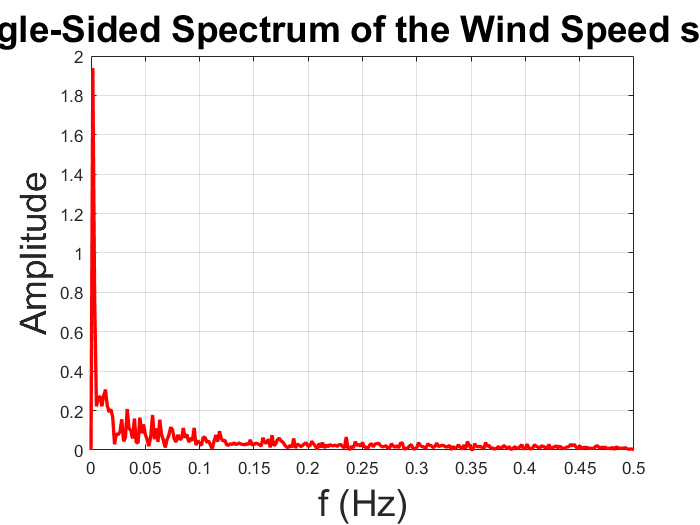

% Fourier Spectrum for wind speed


n = 2^nextpow2(L);         % num of points for FFT

Y = fft(ZM_Wind_speed);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1,'r','LineWidth',2) 

title('Single-Sided Spectrum of the Wind Speed signal','FontSize', 22)
xlabel('f (Hz)','FontSize', 22)
ylabel('Amplitude', 'FontSize', 22)

grid on

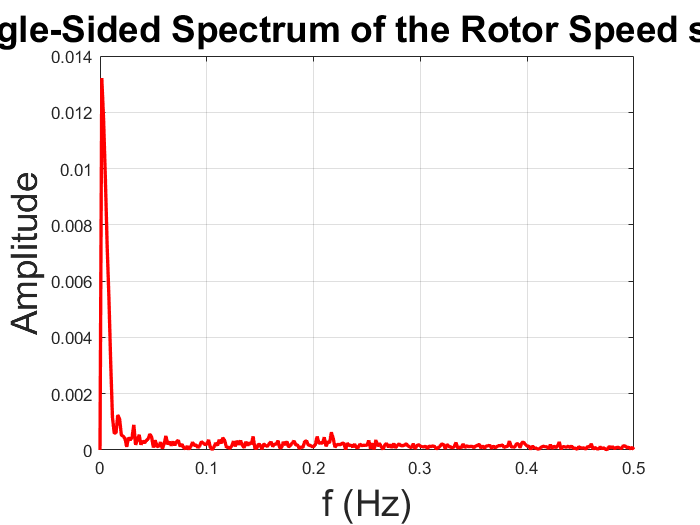

% Fourier Spectrum for Rotor speed

Y1 = fft(ZM_Rotor_rps);
P2 = abs(Y1/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1,'r','LineWidth',2) 

title('Single-Sided Spectrum of the Rotor Speed signal','FontSize', 22)
xlabel('f (Hz)','FontSize', 22)
ylabel('Amplitude', 'FontSize', 22)

grid on

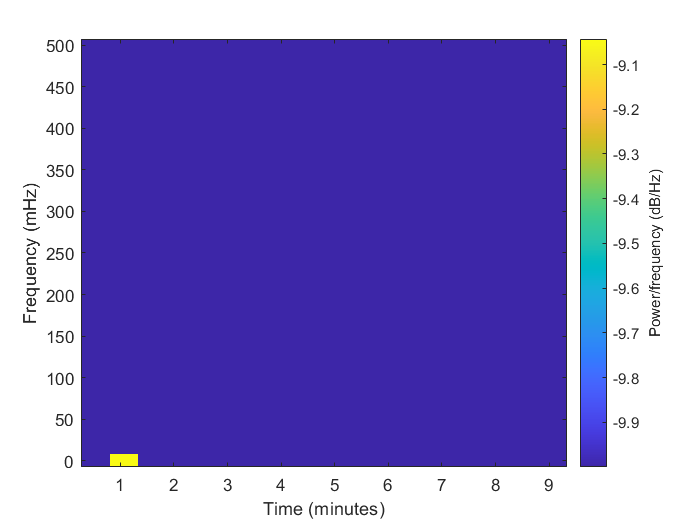

% Spectrogram for Rotor Speed

s = spectrogram(ZM_Rotor_rps);
spectrogram(ZM_Rotor_rps, window(@hanning,64), 32, 64, Fs,'yaxis', 'reassign','MinThreshold', -10)

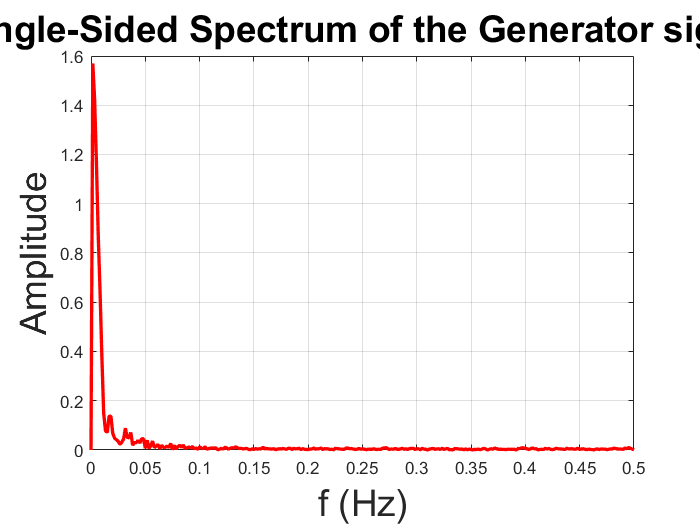

% Fourier Spectrum for Generator speed

Y2 = fft(ZM_Generator_rps);
P2 = abs(Y2/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1,'r','LineWidth',2) 

title('Single-Sided Spectrum of the Generator signal','FontSize', 22)
xlabel('f (Hz)','FontSize', 22)
ylabel('Amplitude', 'FontSize', 22)

grid on

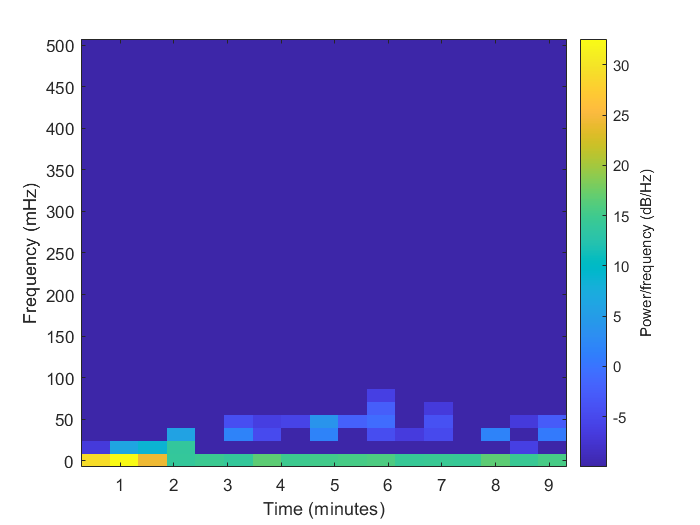

% Spectrogram for Generatortor Speed

s = spectrogram(ZM_Generator_rps);
spectrogram(ZM_Generator_rps, window(@hanning,64), 32, 64, Fs,'yaxis', 'reassign','MinThreshold', -10)

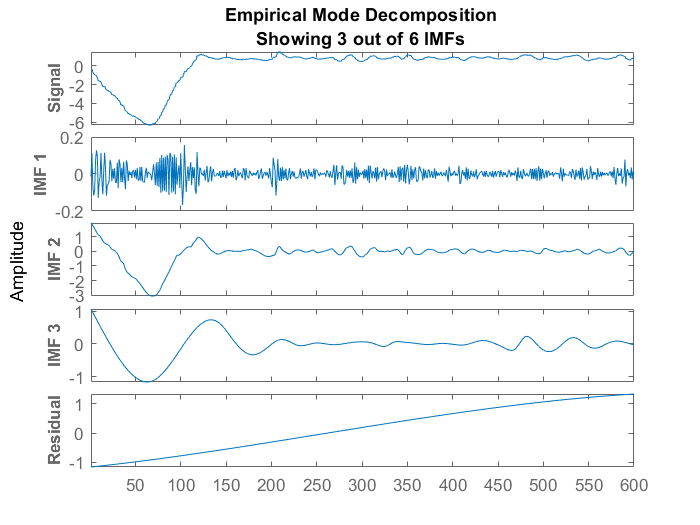

%Hilbert Spectral analysis(x)


emd(ZM_Generator_rps,'MaxNumIMF',6)

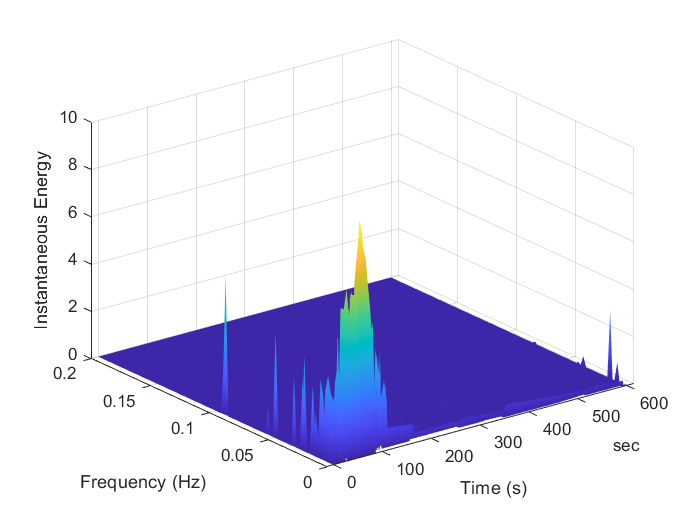

imf = emd(ZM_Generator_rps);
[hs,F,t] = hht(imf,Fs,'FrequencyLimits',[0 .20]);

mesh(seconds(t),F,hs,'EdgeColor','none','FaceColor','interp')
xlabel('Time (s)')
ylabel('Frequency (Hz)')
zlabel('Instantaneous Energy')